%% STEP 1: Load Trained Model
load('TrainedModels/svmModel.mat', 'svmModel', 'mu', 'sigma');  % Trained model and normalization info

%% STEP 2: Load External Dataset
externalData = readtable('Data/ExternalDataForExtraTesting/with output.csv');
disp('Column Names in External Dataset:');

Column Names in External Dataset:


disp(externalData.Properties.VariableNames);

    {'SNR'}    {'Elevation'}    {'Azimuth'}    {'NLOS_Status'}




%% STEP 3: Preprocess the External Data
% -------------------------------------
% Filter criteria:
%   - SNR should be between 20 and 60 dB
%   - Elevation must be > 5 degrees
%   - Azimuth should be within [0, 360]
valid_idx = externalData.SNR >= 20 & externalData.SNR <= 60 & ...
            externalData.Elevation > 5 & ...
            externalData.Azimuth >= 0 & externalData.Azimuth <= 360;

% Apply the filter
externalData = externalData(valid_idx, :);

fprintf('After filtering: %d samples retained from external data.\n', height(externalData));

After filtering: 900 samples retained from external data.


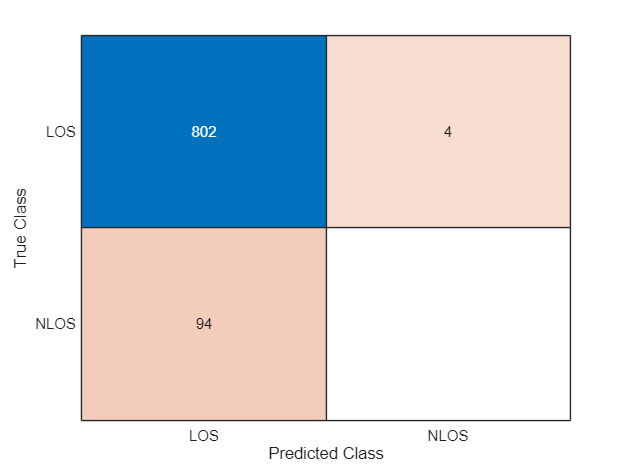


%% STEP 4: Extract Features and Normalize
X_ext = table2array(externalData(:, {'Elevation', 'Azimuth', 'SNR'}));
X_ext_norm = (X_ext - mu) ./ sigma;

%% STEP 5: Predict Labels Using the Trained Model
Y_ext_pred = predict(svmModel, X_ext_norm);

%% STEP 6: Extract True Labels and Evaluate
label_col = externalData{:, end};  % Assumes last column is numeric label (0 = LOS, 1 = NLOS)
Y_ext_true = strings(size(label_col));
Y_ext_true(label_col == 0) = "LOS";
Y_ext_true(label_col == 1) = "NLOS";

% Confusion Matrix
confMat_ext = confusionmat(Y_ext_true, Y_ext_pred);
confusionchart(confMat_ext, {'LOS', 'NLOS'});


% Extract values
TP = confMat_ext(1,1);
FN = confMat_ext(1,2);
FP = confMat_ext(2,1);
TN = confMat_ext(2,2);

% Calculate metrics
accuracy = (TP + TN) / sum(confMat_ext(:));
precision = TP / (TP + FP);
recall = TP / (TP + FN);
f1 = 2 * (precision * recall) / (precision + recall);

% Display Results
fprintf('\nConfusion Matrix (External Dataset After Filtering):\n');


Confusion Matrix (External Dataset After Filtering):


disp(array2table(confMat_ext, 'VariableNames', {'Pred_LOS','Pred_NLOS'}, 'RowNames', {'Actual_LOS','Actual_NLOS'}));

                   Pred_LOS    Pred_NLOS
                   ________    _________

    Actual_LOS       802           4    
    Actual_NLOS       94           0    




fprintf('\nAccuracy: %.2f%%\n', accuracy * 100);


Accuracy: 89.11%


fprintf('Precision: %.2f%%\n', precision * 100);

Precision: 89.51%


fprintf('Recall: %.2f%%\n', recall * 100);

Recall: 99.50%


fprintf('F1 Score: %.2f%%\n', f1 * 100);

F1 Score: 94.24%
